# Taller 2 OCDR

# Consensus Protocol

# Gabriela María Castro Beltrán

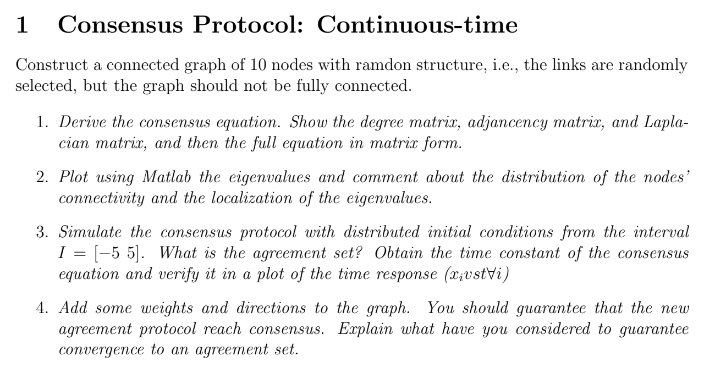

## Ecuación del consenso con Grafo no dirigido y sin pesos

Este código genera un gráfico aleatorio conectado con 10 nodos utilizando una matriz de adyacencia. Primero, se define la probabilidad p=0.3 para la creación de bordes entre nodos. A continuación, se crea una matriz de adyacencia A aleatoria y simétrica, luego se asegura de que el gráfico sea conectado verificando que todos los nodos tengan al menos un borde. El gráfico se construye utilizando la función `graph` de MATLAB y se visualiza con la función `plot`. Posteriormente, se calculan la matriz de grado D y la matriz Laplaciana L del gráfico. Finalmente, se define la ecuación de consenso \frac{dx}{dt} = -Lx, donde x es un vector de 10 elementos simbólicos, representando el estado de cada nodo en el sistema.

% Crear una matriz de adyacencia aleatoria para un gráfico conectado
syms x1 x2 x3 x4 x5 x6 x7 x8 x9 x10 real
x = [x1; x2; x3; x4; x5; x6; x7; x8; x9; x10];
n = 10; % numero de nodoss
p = 0.3; % probabilidad de creación de bordes

% Asegura que sea conectado
while true
    A = rand(n) < p
    A = triu(A, 1)
    A = A + A' %simetrica
    if all(sum(A, 2) > 0) % La función all verifica si todos los elementos del vector lógico son true(conectado).
        disp(true)
        display(A)
        break;
    end
end

A = 10×10 logical array
   0   1   0   0   0   1   0   0   0   1
   0   0   1   1   0   0   1   1   0   1
   1   0   0   1   0   0   0   0   0   0
   0   0   0   1   0   1   0   1   0   0
   0   0   0   1   1   1   0   0   0   0
   1   1   0   0   0   0   0   0   1   1
   1   0   0   0   0   0   0   1   0   0
   0   0   0   0   0   0   1   1   0   0
   0   0   0   0   0   0   1   0   0   1
   0   0   1   1   0   1   1   0   0   0


A = 10×10 logical array
   0   1   0   0   0   1   0   0   0   1
   0   0   1   1   0   0   1   1   0   1
   0   0   0   1   0   0   0   0   0   0
   0   0   0   0   0   1   0   1   0   0
   0   0   0   0   0   1   0   0   0   0
   0   0   0   0   0   0   0   0   1   1
   0   0   0   0   0   0   0   1   0   0
   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   1
   0   0   0   0   0   0   0   0   0   0


A =      0     1     0     0     0     1     0     0     0     1
     1     0     1     1     0     0     1     1     0     1
     0     1     0     1     0     0     0     0     0     0
     0     1     1     0     0     1     0     1     0     0
     0     0     0     0     0     1     0     0     0     0
     1     0     0     1     1     0     0     0     1     1
     0     1     0     0     0     0     0     1     0     0
     0     1     0     1     0     0     1     0     0     0
     0     0     0     0     0     1     0     0     0     1
     1     1     0     0     0     1     0     0     1     0


   1



A =      0     1     0     0     0     1     0     0     0     1
     1     0     1     1     0     0     1     1     0     1
     0     1     0     1     0     0     0     0     0     0
     0     1     1     0     0     1     0     1     0     0
     0     0     0     0     0     1     0     0     0     0
     1     0     0     1     1     0     0     0     1     1
     0     1     0     0     0     0     0     1     0     0
     0     1     0     1     0     0     1     0     0     0
     0     0     0     0     0     1     0     0     0     1
     1     1     0     0     0     1     0     0     1     0


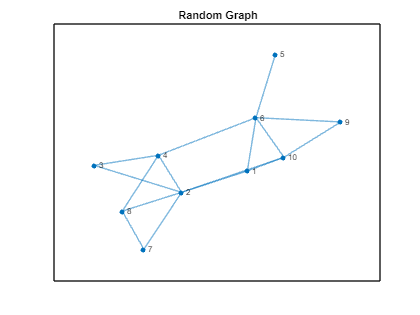


G = graph(A);

% Plot the graph
figure;
plot(G);
title('Random Graph');


% Matriax de grado y Laplaciano
D = diag(degree(G))

D =      3     0     0     0     0     0     0     0     0     0
     0     6     0     0     0     0     0     0     0     0
     0     0     2     0     0     0     0     0     0     0
     0     0     0     4     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0
     0     0     0     0     0     5     0     0     0     0
     0     0     0     0     0     0     2     0     0     0
     0     0     0     0     0     0     0     3     0     0
     0     0     0     0     0     0     0     0     2     0
     0     0     0     0     0     0     0     0     0     4


L = D - A

L =      3    -1     0     0     0    -1     0     0     0    -1
    -1     6    -1    -1     0     0    -1    -1     0    -1
     0    -1     2    -1     0     0     0     0     0     0
     0    -1    -1     4     0    -1     0    -1     0     0
     0     0     0     0     1    -1     0     0     0     0
    -1     0     0    -1    -1     5     0     0    -1    -1
     0    -1     0     0     0     0     2    -1     0     0
     0    -1     0    -1     0     0    -1     3     0     0
     0     0     0     0     0    -1     0     0     2    -1
    -1    -1     0     0     0    -1     0     0    -1     4


% Consensus equation: dx/dt = -Lx
consensus_eq = -L * x

$$consensus\_eq = \left(\begin{array}{c} x_{2}-3\,x_{1}+x_{6}+x_{10}\\ x_{1}-6\,x_{2}+x_{3}+x_{4}+x_{7}+x_{8}+x_{10}\\ x_{2}-2\,x_{3}+x_{4}\\ x_{2}+x_{3}-4\,x_{4}+x_{6}+x_{8}\\ x_{6}-x_{5}\\ x_{1}+x_{4}+x_{5}-5\,x_{6}+x_{9}+x_{10}\\ x_{2}-2\,x_{7}+x_{8}\\ x_{2}+x_{4}+x_{7}-3\,x_{8}\\ x_{6}-2\,x_{9}+x_{10}\\ x_{1}+x_{2}+x_{6}+x_{9}-4\,x_{10} \end{array}\right)$$

A continuación, se crea un gráfico de dispersión de los valores propios, donde el eje x representa el índice de cada valor propio y el eje y muestra el valor correspondiente.

% Eigenvalores del Laplaciano
eigenvalues = sort(eig(L))

eigenvalues =    -0.0000
    0.6902
    1.2048
    1.6492
    2.4386
    3.1716
    4.5944
    4.8279
    6.0649
    7.3585


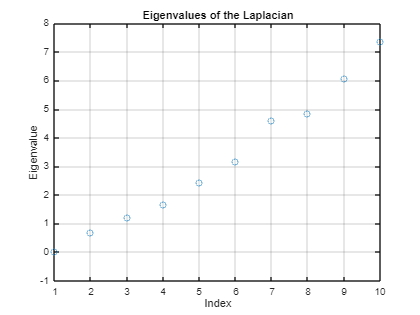


% Plot
figure;
plot(eigenvalues, 'o');
title('Eigenvalues of the Laplacian');
xlabel('Index');
ylabel('Eigenvalue');
grid on;

Este código resuelve un sistema de consenso utilizando dinámicas basadas en la matriz Laplaciana L. Primero, se definen las condiciones iniciales como un vector de 10 elementos aleatorios entre -5 y 5. Luego, se especifica el intervalo de tiempo tspan=[0,5] durante el cual se resolverá el sistema. La dinámica de consenso se resuelve numéricamente utilizando la función `ode45`. Además, se calcula el segundo valor propio más pequeño de la matriz Laplaciana, conocido como el valor de Fiedler�, que se usa para obtener la constante de tiempo�, que caracteriza la velocidad de convergencia del sistema. Finalmente, se grafica la evolución temporal de los estados del sistema, mostrando cómo los nodos del gráfico convergen hacia un acuerdo a lo largo del tiempo.

% Condiciones iniciales
x0 = -5 + 10*rand(n, 1)

x0 =    -3.3782
    2.9428
   -1.8878
    0.2853
   -3.3435
    1.0198
   -2.3703
    1.5408
    1.8921
    2.4815



% Time span
tspan = [0 5];

% Consensus dynamics
consensus_dynamics = @(t, x) -L*x

consensus_dynamics = function_handle with value:
    @(t,x)-L*x



% Fiedler value (El segundo eigenvalor más pequeño)
lambda_2 = eigenvalues(2);

% Constante de tiempo (inverse of Fiedler value)
time_constant = 1 / lambda_2

time_constant = 1.4488


% Solve
[t, x] = ode45(consensus_dynamics, tspan, x0);

% Agreement set (promedio)
agreement_set = mean(x0)

agreement_set = -0.0817


% últimpo valor al cual llegan en el acuerdo
agreement_set2 = x(end)

agreement_set2 = -0.0829

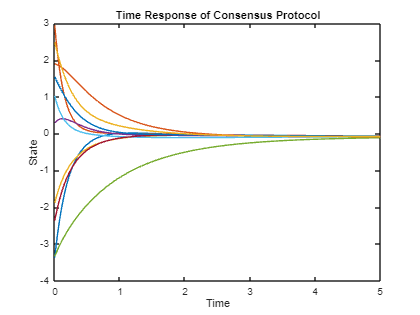


% Plot 
figure;
plot(t, x);
title('Time Response of Consensus Protocol');
xlabel('Time');
ylabel('State');

## Ecuación del consenso con Grafo dirigido y con pesos

Se modifica la matriz de adyacencia Apara permitir que las conexiones no sean necesariamente simétricas(esto se hace para que la respuesta sea diferente al no dirigido). Inicialmente, se define un vector de nodos � con 10 variables simbólicas. Luego, se recorre la matriz de adyacencia A y, de manera aleatoria, se elimina una de las conexiones opuestas entre dos nodos (es decir, si A(i,j)=1 y A(j,i)=1, una de las conexiones se elimina aleatoriamente, haciendo que el gráfico sea dirigido y asimétrico). Después, se verifica que el gráfico siga siendo conectado, es decir, que cada nodo tenga al menos una conexión. A continuación, se añaden pesos aleatorios a las aristas del gráfico, generando una nueva matriz�, que se asegura de que el gráfico siga siendo conectado. Se crea un gráfico dirigido utilizando `digraph` y se visualiza. Posteriormente, se calculan las matrices de grado ponderado Dw y la matriz Laplaciana Lw del gráfico. Finalmente, se define la ecuación de consenso, pero ahora en un gráfico dirigido y ponderado.

syms x1 x2 x3 x4 x5 x6 x7 x8 x9 x10 real
x_w = [x1; x2; x3; x4; x5; x6; x7; x8; x9; x10];
% Forzar asimetría manualmente
for i = 1:n
    for j = i+1:n
        if A(i, j) == 1 && rand() < 0.5
            A(j, i) = 0; % Eliminar conexión opuesta
        elseif A(j, i) == 1 && rand() < 0.5
            A(i, j) = 0; % Eliminar conexión opuesta
        end
    end
end
disp(A)

     0     1     0     0     0     1     0     0     0     1
     0     0     0     1     0     0     0     1     0     1
     0     1     0     0     0     0     0     0     0     0
     0     1     1     0     0     1     0     0     0     0
     0     0     0     0     0     1     0     0     0     0
     0     0     0     1     0     0     0     0     1     0
     0     1     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     1     0     0     0
     0     0     0     0     0     0     0     0     0     1
     0     0     0     0     0     1     0     0     0     0



% Asegurar que sea conectado
while true
    %pesos
    W = rand(n)
    A_weighted = A .* W % aplicar los pesos
    if all(sum(A_weighted, 2) > 0) % La función all verifica si todos los elementos del vector lógico son true(conectado).
        disp(true)
        break;
    end
end

W =     0.1455    0.4018    0.4909    0.0965    0.0430    0.6868    0.4468    0.3507    0.8443    0.9049
    0.1361    0.0760    0.4893    0.1320    0.1690    0.1835    0.3063    0.9390    0.1948    0.9797
    0.8693    0.2399    0.3377    0.9421    0.6491    0.3685    0.5085    0.8759    0.2259    0.4389
    0.5797    0.1233    0.9001    0.9561    0.7317    0.6256    0.5108    0.5502    0.1707    0.1111
    0.5499    0.1839    0.3692    0.5752    0.6477    0.7802    0.8176    0.6225    0.2277    0.2581
    0.1450    0.2400    0.1112    0.0598    0.4509    0.0811    0.7948    0.5870    0.4357    0.4087
    0.8530    0.4173    0.7803    0.2348    0.5470    0.9294    0.6443    0.2077    0.3111    0.5949
    0.6221    0.0497    0.3897    0.3532    0.2963    0.7757    0.3786    0.3012    0.9234    0.2622
    0.3510    0.9027    0.2417    0.8212    0.7447    0.4868    0.8116    0.4709    0.4302    0.6028
    0.5132    0.9448    0.4039    0.0154    0.1890    0.4359    0.5328    0.2305    0.1

A_weighted =          0    0.4018         0         0         0    0.6868         0         0         0    0.9049
         0         0         0    0.1320         0         0         0    0.9390         0    0.9797
         0    0.2399         0         0         0         0         0         0         0         0
         0    0.1233    0.9001         0         0    0.6256         0         0         0         0
         0         0         0         0         0    0.7802         0         0         0         0
         0         0         0    0.0598         0         0         0         0    0.4357         0
         0    0.4173         0         0         0         0         0         0         0         0
         0         0         0    0.3532         0         0    0.3786         0         0         0
         0         0         0         0         0         0         0         0         0    0.6028
         0         0         0         0         0    0.4359         0        

   1




G2=digraph(A_weighted)

G2 =   digraph with properties:

    Edges: [18×2 table]
    Nodes: [10×0 table]


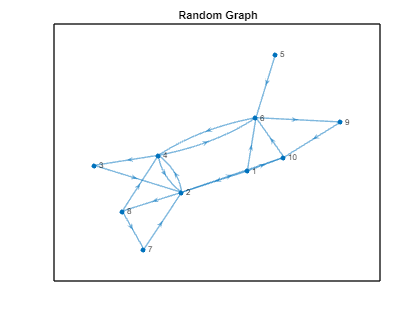


% Plot the graph
figure;
plot(G2);
title('Random Graph');


% Matriz de grado y Laplaciano
D_w = diag(sum(A_weighted, 2))

D_w =     1.9935         0         0         0         0         0         0         0         0         0
         0    2.0507         0         0         0         0         0         0         0         0
         0         0    0.2399         0         0         0         0         0         0         0
         0         0         0    1.6490         0         0         0         0         0         0
         0         0         0         0    0.7802         0         0         0         0         0
         0         0         0         0         0    0.4955         0         0         0         0
         0         0         0         0         0         0    0.4173         0         0         0
         0         0         0         0         0         0         0    0.7318         0         0
         0         0         0         0         0         0         0         0    0.6028         0
         0         0         0         0         0         0         0         0     

L_w = D_w - A_weighted

L_w =     1.9935   -0.4018         0         0         0   -0.6868         0         0         0   -0.9049
         0    2.0507         0   -0.1320         0         0         0   -0.9390         0   -0.9797
         0   -0.2399    0.2399         0         0         0         0         0         0         0
         0   -0.1233   -0.9001    1.6490         0   -0.6256         0         0         0         0
         0         0         0         0    0.7802   -0.7802         0         0         0         0
         0         0         0   -0.0598         0    0.4955         0         0   -0.4357         0
         0   -0.4173         0         0         0         0    0.4173         0         0         0
         0         0         0   -0.3532         0         0   -0.3786    0.7318         0         0
         0         0         0         0         0         0         0         0    0.6028   -0.6028
         0         0         0         0         0   -0.4359         0         0     


% Consensus equation: dx/dt = -Lx
consensus_eq_w = -L_w * x_w;

A continuación, se crea un gráfico de dispersión de los valores propios, donde el eje x representa el índice de cada valor propio y el eje y muestra el valor correspondiente.

% Eigenvalores del Laplaciano
eigenvalues_w = sort(real(eig(L_w)))

eigenvalues_w =     0.0000
    0.1540
    0.3152
    0.7460
    0.7460
    0.7802
    1.0312
    1.6558
    1.9746
    1.9935


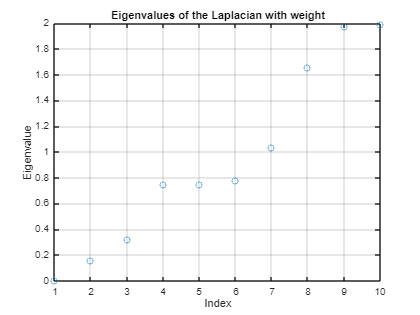


% Plot
figure;
plot(eigenvalues_w, 'o');
title('Eigenvalues of the Laplacian with weight');
xlabel('Index');
ylabel('Eigenvalue');
grid on;

Se simula la dinámica de consenso en un gráfico dirigido y ponderado, en donde se calcula el valor de Fiedler \lambda_2_w y la constante de tiempo, que determina la velocidad de convergencia del sistema. Con condiciones iniciales aleatorias, se resuelve la ecuación diferencial dxdt=−Lw usando `ode45` para obtener la evolución de los estados del sistema. Al final, se extrae el estado final como el acuerdo alcanzado, y se grafica cómo los estados de los nodos evolucionan a lo largo del tiempo.


% Fiedler value (El segundo eigenvalor más pequeño)
lambda_2_w = eigenvalues_w(2);

% Time constant (inverse of Fiedler value)
time_constant_w = 1 / lambda_2_w

time_constant_w = 6.4919


% Condiciones iniciales
x0_w = -5 + 10*rand(n, 1);

% Time span
tspan = [0 30];

% Consensus dynamics with new Laplacian
consensus_dynamics_weighted = @(t, x_w) -L_w * x_w;

% Solve
[t, x_w] = ode45(consensus_dynamics_weighted, tspan, x0_w);

% últimpo valor al cual llegan en el acuerdo
agreement_set = x_w(end)

agreement_set = -1.1456

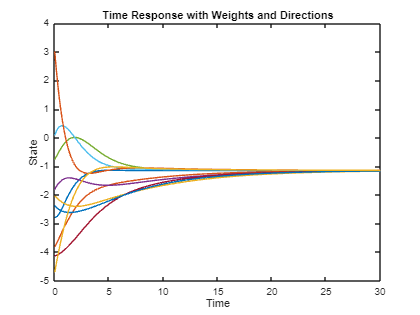



% Plot
figure;
plot(t, x_w);
title('Time Response with Weights and Directions');
xlabel('Time');
ylabel('State');

## Análisis de condiciones para llegar al consenso

Para que el protocolo de consenso con pesos y direcciones llegue al consenso, es necesario tener en cuenta lo siguiente:

- **Conectividad del grafo dirigido: **Aunque el grafo esté dirigido, debe ser fuertemente conectado, es decir, debe existir un camino dirigido entre cualquier par de nodos. Esto garantiza que la información fluya entre todos los nodos, lo que es esencial para que el sistema converja.

- **Pesos adecuados**: Los pesos asignados a las conexiones entre los nodos deben ser apropiados, de modo que la influencia de cada nodo sobre los demás sea equilibrada. Si los pesos son demasiado grandes o pequeños, el sistema puede volverse inestable o lento para converger.

- **Valor propio de Fiedler**: El segundo valor propio más pequeño de la matriz de Laplaciana debe ser positivo. Este valor es fundamental porque la constante de tiempo, que define la velocidad de convergencia del sistema, está inversamente relacionada con λ2�. Un valor pequeño implica una convergencia más lenta.

- **Dirección de las conexiones**: Aunque las conexiones sean asimétricas, se debe garantizar que las direcciones no creen ciclos que impidan el flujo de información hacia todos los nodos. Además, las conexiones deben ser suficientes para que cada nodo pueda influir en los demás.

- **Condiciones iniciales distribuidas**: Al utilizar condiciones iniciales distribuidas dentro de un rango, el sistema debe ser capaz de converger hacia un único valor (el conjunto de acuerdo) independientemente de las posiciones iniciales, siempre que las condiciones anteriores sean satisfechas.